%% Lab Flux Test Set-Point Calculations
%
% Lincoln Scheer
% 25 April 2024
%
%
% The purpose of this script is to determine MFC set-points that will
% simulate expected flux ranges in the lab environment.

clc, clear, close all

%% System Assumptions

% Chamber Surface Area
As = 0.064844702; % [m^2]

% Environment Assumptions
P = 78269.5628; % [Pa]
T = 293.15; % [K]

% Expected Flux Ranges
F_l = 0.5; % low range [umol/m^2/s]
F_h = 10; % high range [umol/m^2/s]

% Delivery Tank Concentration
Ctank = 395.802; % [ppm]

% MFC Size Used
MFC_q = 2.5; % [lpm]

% Resolution
res = 10;

% Unit Conversion Functions
ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);  % ppm to mol/m^3
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;    % mol/m^3 to ppm
lpm_to_cms = @(lpm) lpm/60000;              % liters per min to m^3 per min
cms_to_lpm = @(cms) cms*60000;              % m^3 per min to liters per min

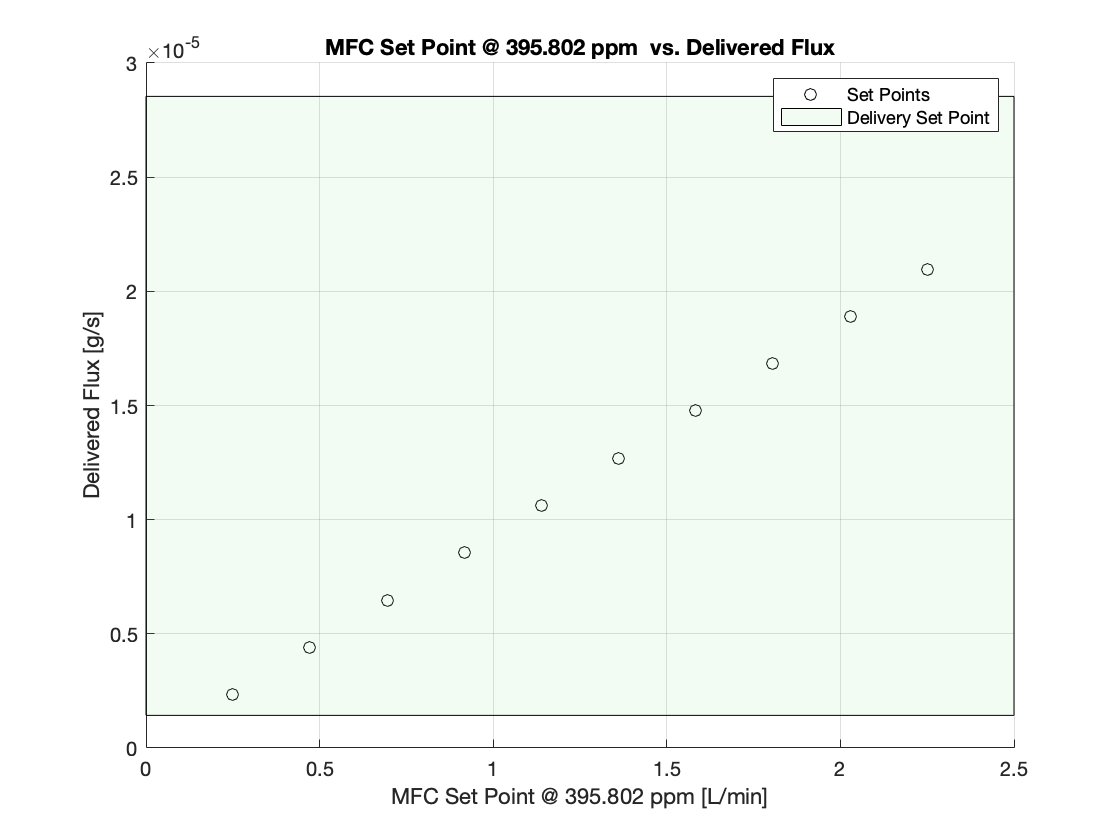

% Converting Flux Delivery from [umol/m^2/s] to [g/s]
w_F_l = F_l * 44.0095 * 1e-6 * As;
w_F_h = F_h * 44.0095 * 1e-6 * As; 

% Calculate Possible Setpoint Range % [m^3/s]
mfc_low = lpm_to_cms(MFC_q*0.1);
mfc_high = lpm_to_cms(MFC_q - MFC_q*0.1);
mfc_set_pt_rng = linspace(mfc_low, mfc_high, res);

% Convert Tank Concentration from [ppm] to [g/m^3]
w_Ctank = ppm_to_mol(Ctank)*44.0096;

% Calculate Possible Delivery Range [g/s]
dlv_set_pt_rng = mfc_set_pt_rng * w_Ctank;

% Plotting Set Points vs. Delivered Flux
%
%   Green shaded area indicates desired delivered fluxes that we want, if
%   delivery set points are outside of green range, adjust the Ctank
%   concentration delivered or the MFC size used.
%
figure()
hold on
plot(cms_to_lpm(mfc_set_pt_rng), dlv_set_pt_rng, 'ko')
patch([min(xlim) max(xlim) max(xlim) min(xlim)], [w_F_l w_F_l w_F_h, w_F_h], [0.5 0.9 0.5], 'FaceAlpha', 0.1)
title("MFC Set Point @ " + Ctank + " ppm  vs. Delivered Flux")
legend(["Set Points", "Delivery Set Point"])
xlabel("MFC Set Point @ " + Ctank + " ppm [L/min]")
ylabel("Delivered Flux [g/s]")
grid on

set_points = table(cms_to_lpm(mfc_set_pt_rng)', dlv_set_pt_rng', 'VariableNames', ["Set Point [LPM]", "Delivered Flux [g/s]"])

set_points = 10×2 table
    Set Point [LPM]    Delivered Flux [g/s]
    _______________    ____________________

           0.25             2.3308e-06     
        0.47222             4.4026e-06     
        0.69444             6.4745e-06     
        0.91667             8.5463e-06     
         1.1389             1.0618e-05     
         1.3611              1.269e-05     
         1.5833             1.4762e-05     
         1.8056             1.6834e-05     
         2.0278             1.8905e-05     
           2.25             2.0977e-05     


set_points.("Delivered Flux [g/day]") = (set_points.("Delivered Flux [g/s]")*60*60*24)/As

set_points = 10×3 table
    Set Point [LPM]    Delivered Flux [g/s]    Delivered Flux [g/day]
    _______________    ____________________    ______________________

           0.25             2.3308e-06                 3.1056        
        0.47222             4.4026e-06                 5.8661        
        0.69444             6.4745e-06                 8.6267        
        0.91667             8.5463e-06                 11.387        
         1.1389             1.0618e-05                 14.148        
         1.3611              1.269e-05                 16.908        
         1.5833             1.4762e-05                 19.669        
         1.8056             1.6834e-05                 22.429        
         2.0278             1.8905e-05                  25.19        
           2.25             2.0977e-05                  27.95        


load('q_calib.mat')
set_points.("Corrected Set Point [LPM]") = predict(Q_actual, cms_to_lpm(mfc_set_pt_rng)')

set_points = 10×4 table
    Set Point [LPM]    Delivered Flux [g/s]    Delivered Flux [g/day]    Corrected Set Point [LPM]
    _______________    ____________________    ______________________    _________________________

           0.25             2.3308e-06                 3.1056                     0.24971         
        0.47222             4.4026e-06                 5.8661                     0.46628         
        0.69444             6.4745e-06                 8.6267                     0.68284         
        0.91667             8.5463e-06                 11.387                      0.8994         
         1.1389             1.0618e-05                 14.148                       1.116         
         1.3611              1.269e-05                 16.908                      1.3325         
         1.5833             1.4762e-05         